# State feedback control for DC motor position

Project part 2 is pretty the same as part 1, but instead of using pole placement method to determine the $K_c$ values, I want you to use the LQR method. Also note that I removed the requirement for compensating for distrubance, as this will be more complicated to do in this case. 

Consider the following system 

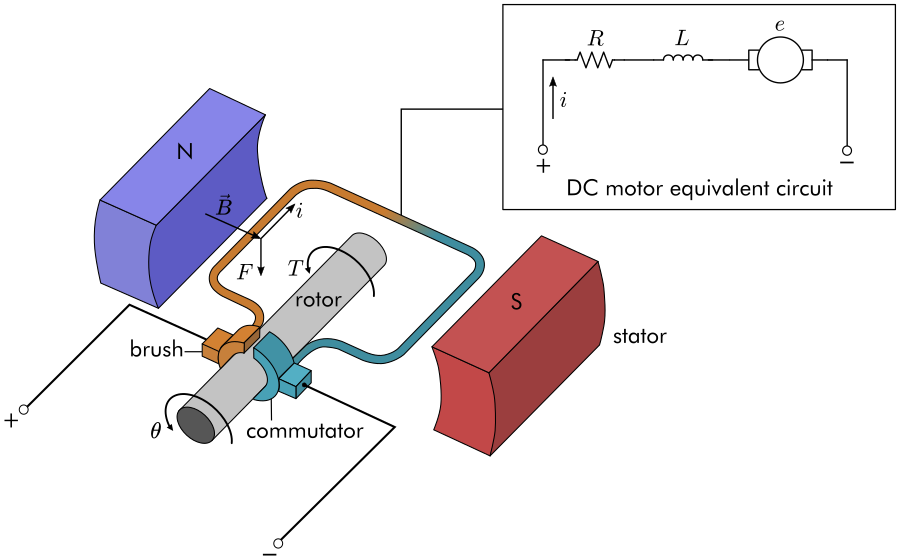


$$iR + L \frac{di}{dt} + k_e \dot{\theta} = v$$


 
$$J \ddot{\theta} + b \dot{\theta}  = k_m i$$
      

We will assume $K = k_e = k_m$

## State space representation

The differential equations from above can also be expressed in state-space form by choosing the motor position, motor speed and armature current as the state variables. Again the armature voltage is treated as the input and the rotational position is chosen as the output.

State vector: $\mathbf{x} = \left[ \begin{array}{c} 
\theta \\
\dot{\theta} \\
i

\end{array} \right]$


$$\dot{\mathbf{x}}  = \left[ \begin{array}{c} 
\theta \\
\ddot{\theta} \\
\dot{i}
\end{array} \right]   =  \left[ \begin{array}{ccc}
0 & 1 & 0 \\
0 & -\frac{b}{J} &  \frac{K}{J} \\
0 & -\frac{K}{L} & -\frac{R}{L} 
\end{array} \right] \left[ \begin{array}{c} 
\theta \\
\dot{\theta} \\
i
\end{array} \right]

  +  \left[ \begin{array}{c} 
0 \\
0 \\
\frac{1}{L}  
\end{array} \right] v  \\ 
$$


## Design requirements

We will want to be able to position the motor very precisely, thus the steady-state error of the motor position should be zero when given a commanded position. We will also want the steady-state error due to a constant disturbance to be zero as well. The other performance requirement is that the motor reaches its final position very quickly without excessive overshoot. In this case, we want the system to have a settling time of 40 ms and an overshoot smaller than 16%.

If we simulate the reference input by a unit step input, then the motor position output should have:

- Settling time less than 40 milliseconds

- Overshoot less than 16%

- No steady-state error

## Motor parameters

Do not change these values. 

J = 0.01; %kg.m^2
b = 0.1; %N.m.s 
K = 0.01; %V/rad/s
R = 1; %Ohm
L = 0.5; %H


## Problem statement

Design a state feedback controller to achieve all the design requirements provided above. Your submission should have detailed explanation your methodology along with evidence showing that you have met the requirements. 

Use LQR method to compute the feedback gain $K_c$.

## State feedback controller

#### System analysis

%setting up the state space model 
A = [0,1,0; 0,-b/J, K/J; 0, -K/L -R/L]; 
B = [0;0; 1/L]; 
C = [1 0 0];
D = 0; 
dcMotorSS = ss(A,B,C,D); 


#### Feedback gain computation

Since we have to reduce the steady state error for both angle measurement, we will penalize the angle value. We will also penalize the angular velocity to reduce  settling time.

Q = diag([100,10,1]); 
R = 1; 
Kc = lqr(dcMotorSS,Q,R); 
sys_cl = ss(A-B*Kc,B,C,D); 
Nbar = 1/dcgain(sys_cl);
newSys_cl = Nbar*sys_cl;
info = stepinfo(newSys_cl); 
measurements = [info.SettlingTime,info.Overshoot,dcgain(newSys_cl)]; 
SettlingTime = info.SettlingTime; Overshoot = info.Overshoot; SteadyState = dcgain(newSys_cl); 
requirements = table(SettlingTime, Overshoot, SteadyState)

requirements = 1×3 table
    SettlingTime    Overshoot    SteadyState
    ____________    _________    ___________
       5.9988           0             1     